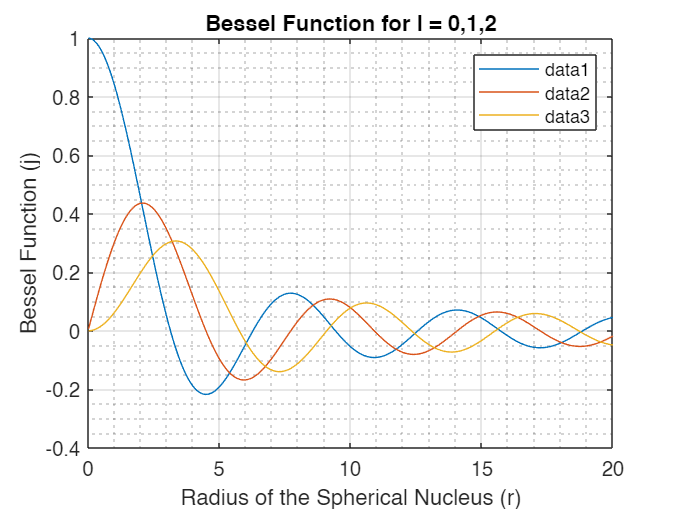

clear all
clc
syms l

l=0;
% Define the function
f = @(r) sin(r)./r;

% Set the range of r values
r = linspace(0, 20, 1000);

% Calculate the Bessel function values
j = f(r);

% Plot the results
plot(r, j)
xlabel('Radius of the Spherical Nucleus (r)')
ylabel('Bessel Function (j)')
title('Bessel Function for l = 0,1,2')

hold on


l=1;
% Define the function
f = @(r) [sin(r)./(r.^2)]-[cos(r)./r];

% Set the range of r values
r = linspace(0, 20, 1000);

% Calculate the Bessel function values
j = f(r);

% Plot the results
plot(r, j);


hold on
l=2;
% Define the function
f = @(r) [3*sin(r)./(r.^3)]-[3*cos(r)./r.^2]-[sin(r)./r];

% Set the range of r values
r = linspace(0, 20, 1000);

% Calculate the Bessel function values
j = f(r);

% Plot the results
plot(r, j);


grid on
grid minor

legend('show')
hold off


%using newton raphson method
%finding the solution for l=0

% Define the function and its derivative
f = @(r) sin(r)./r;
df = @(r) cos(r)./r - sin(r)./(r.^2);

% Set the tolerance
tol = 1e-6;

% Set the initial guesses
x0 = [3, 6, 9, 12, 15, 18];

% Initialize variables for the iteration
roots = zeros(size(x0));
errors = cell(size(x0));

% Perform the Newton-Raphson iteration for each initial guess
for i = 1:length(x0)
    x = x0(i);
    error = inf;
    errors{i} = [];
    while error > tol
        x_new = x - f(x)/df(x);
        error = abs(x_new - x);
        errors{i}(end+1) = error;
        x = x_new;
    end
    roots(i) = x;
end

% Display the results
disp(['The roots of the function for l=0 are approximately: ', num2str(roots)])

The roots of the function for l=0 are approximately: 3.14159      6.28319      9.42478      12.5664       15.708      18.8496


for i = 1:length(errors)
    disp(['Errors for root ', num2str(i), ': ', num2str(errors{i})])
end

Errors for root 1: 0.13608   0.0055024  9.6155e-06   2.943e-11
Errors for root 2: 0.27754   0.0056353  5.0035e-06  3.9844e-12
Errors for root 3: 0.43067   0.0058971  3.7534e-06  1.4939e-12
Errors for root 4: 0.60386    0.037621  0.00012954  1.3346e-09
Errors for root 5: 0.80978     0.10284   0.0010178  6.5612e-08
Errors for root 6: 1.0697     0.22645   0.0062834  2.0132e-06  2.1316e-13



%finding the solution for l=1
 
% Define the function and its derivative
f = @(r) [sin(r)./(r.^2)]-[cos(r)./r];
df = @(r) [-2*sin(r)./(r.^3)] - [cos(r)./(r.^2)] + [sin(r)./r];

% Set the tolerance
tol = 1e-6;

% Set the initial guesses
x0 = [1, 3, 5];

% Initialize variables for the iteration
roots = zeros(size(x0));

% Perform the Newton-Raphson iteration for each initial guess
for i = 1:length(x0)
    x = x0(i);
    error = inf;
    while error > tol
        x_new = x - f(x)/df(x);
        error = abs(x_new - x);
        x = x_new;
    end
    roots(i) = x;
end

% Display the results
disp(['The roots of the function for l=1 are approximately: ', num2str(roots)])

The roots of the function for l=1 are approximately: -4.4934     -4.4934      4.4934




%finding the solution for l=2

% Define the function and its derivative
f = @(r) [3*sin(r)./(r.^3)]-[3*cos(r)./r.^2]-[sin(r)./r];
df = @(r) [-9*sin(r)./(r.^4)] + [6*cos(r)./(r.^3)] + [3*cos(r)./(r.^2)] + [sin(r)./r];

% Set the tolerance
tol = 1;

% Set the initial guesses
x0 = [1, 2];

% Initialize variables for the iteration
roots = zeros(size(x0));

% Perform the Newton-Raphson iteration for each initial guess
for i = 1:length(x0)
    x = x0(i);
    error = inf;
    while error > tol
        x_new = x - f(x)/df(x);
        error = abs(x_new - x);
        x = x_new;
    end
    roots(i) = x;
end

% Display the results
disp(['The roots of the function for l=2 are approximately: ', num2str(roots)])

The roots of the function for l=2 are approximately: 1.0332      2.2914
